## Comparison of methods using the final models

### Initialisation

% CLear all
clear
clc
clf
close all
% load the letter dataset 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



### Load the models

load treeBaggerModel.mat
load nBayesModel.mat
load treeModel.mat

### Random Forest Method

#### Test the Random Forest model

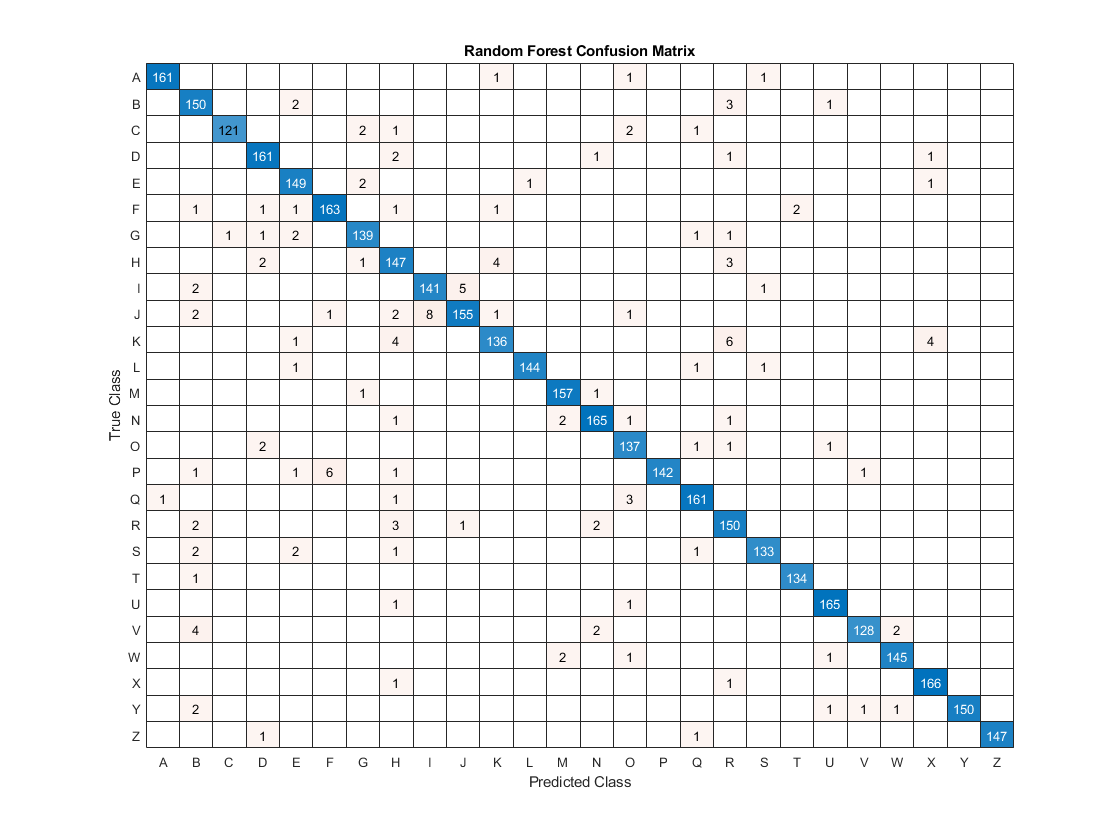

[xTest, yTest] = letterDataset.extractXYFromTable(letterDataset.testTable);
startTime = cputime;
[predictionResult, ~] = predict(treeBaggerModel, xTest(:,:));
rfPredictTime = cputime - startTime;
% errors
rfMisclassifiedCount = sum(predictionResult ~= categorical(table2array(yTest)));
[rfAccuracy, rfPrecision, rfRecall, ...
  rfF1] = CalcUtil.calculateMeasuresFromExpectPredict(table2array(yTest), predictionResult);
y = categorical(table2cell(yTest));
pred = categorical(predictionResult);
% Plot confusion matrix
PlotUtil.plotConfusionChart(y, pred, "Random Forest Confusion Matrix");

### Naive Bayes Method

#### Test the Model

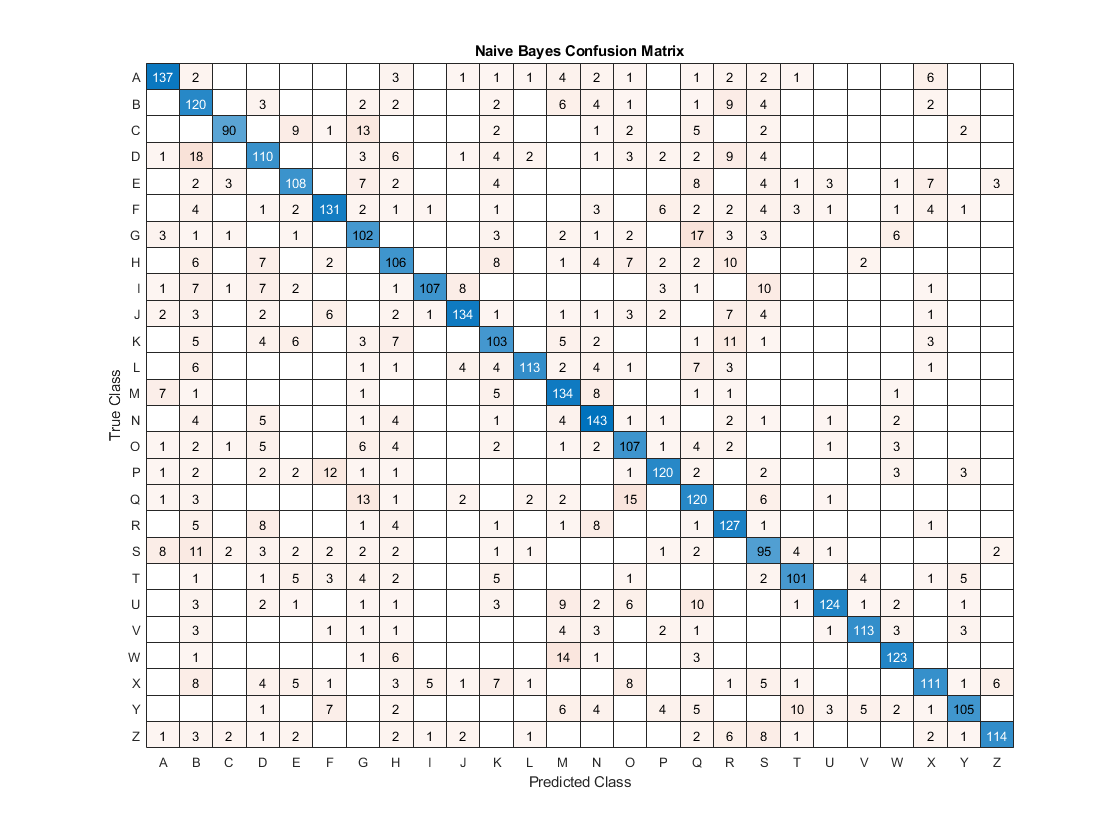

[xTest, yTest] = letterDataset.extractXYFromTable(letterDataset.testTable);
startTime = cputime;
[predictionResult, ~] = predict(nBayesModel, xTest(:,:));
nbPredictTime = cputime - startTime;
% errors
nbMisclassifiedCount = sum(predictionResult ~= categorical(table2array(yTest)));
[nbAccuracy, nbPrecision, nbRecall, ...
  nbF1] = CalcUtil.calculateMeasuresFromExpectPredict(table2array(yTest), predictionResult);
y = categorical(table2cell(yTest));
pred = categorical(predictionResult);
% Plot confusion matrix
PlotUtil.plotConfusionChart(y, pred, "Naive Bayes Confusion Matrix");

### Decision Tree Method

#### Test the Model

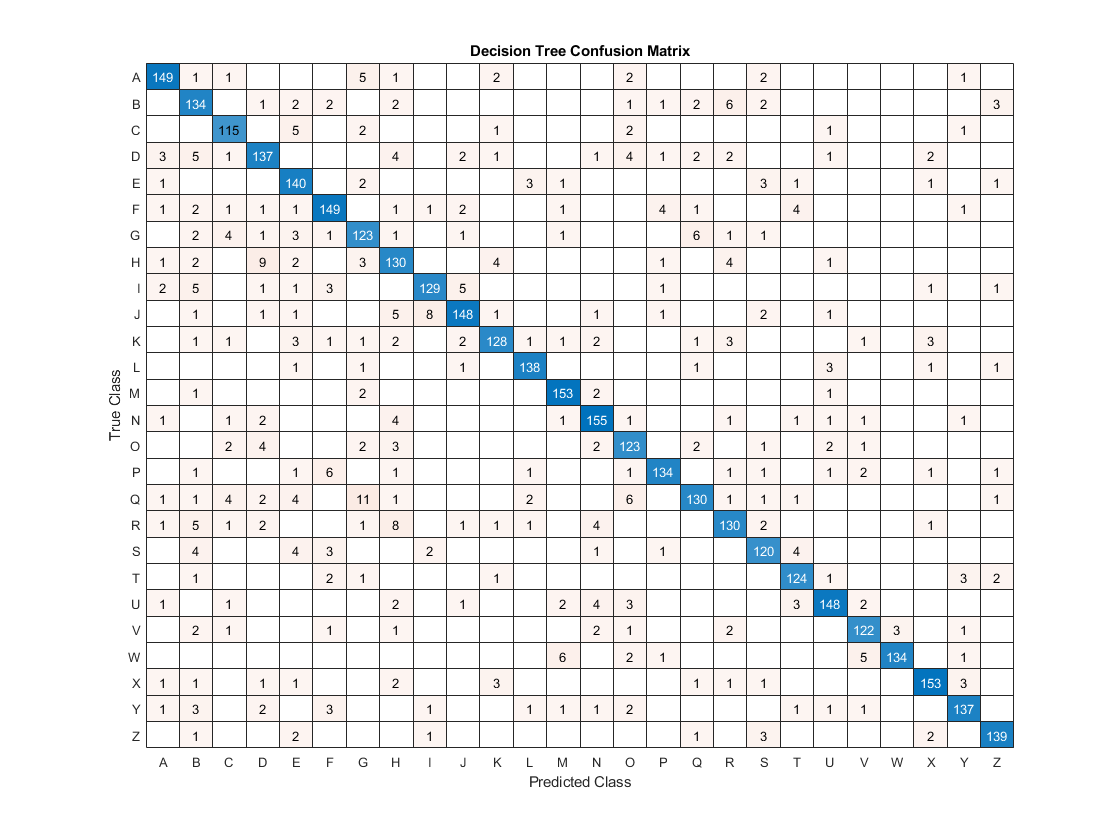

[xTest, yTest] = letterDataset.extractXYFromTable(letterDataset.testTable);
startTime = cputime;
[predictionResult, ~] = predict(treeModel, xTest(:,:));
dtPredictTime = cputime - startTime;
% errors
dtMisclassifiedCount = sum(predictionResult ~= categorical(table2array(yTest)));
yTestArray = table2array(yTest);
[dtAccuracy, dtPrecision, dtRecall, ...
  dtF1] = CalcUtil.calculateMeasuresFromExpectPredict(yTestArray, predictionResult);
y = categorical(table2cell(yTest));
%pred = categorical(predictionResult);
PlotUtil.plotConfusionChart(y, predictionResult, "Decision Tree Confusion Matrix");

### Final Prediction Result Comparison

Method = ["Random Forest"; "Naive Bayes"; "Decision Tree"];
MisclassificationCount = [rfMisclassifiedCount; nbMisclassifiedCount; dtMisclassifiedCount];
Accuracy = [rfAccuracy; nbAccuracy; dtAccuracy];
Precision = [rfPrecision; nbPrecision; dtPrecision];
Recall = [rfRecall; nbRecall; dtRecall];
F1 = [rfF1; nbF1; dtF1];
PredictionTime = [rfPredictTime; nbPredictTime; dtPredictTime];
resultsTable = table(Method, MisclassificationCount, Accuracy, Precision, Recall, F1, PredictionTime);
disp(resultsTable);

        Method         MisclassificationCount    Accuracy    Precision    Recall       F1       PredictionTime
    _______________    ______________________    ________    _________    _______    _______    ______________

    "Random Forest"              153             0.96175      0.96163     0.96303    0.96233             3    
    "Naive Bayes"               1002              0.7495      0.74906     0.76753    0.75818        4.6406    
    "Decision Tree"              478              0.8805       0.8811     0.88212    0.88161         0.125    



For this dataset, the random forest method is the best performer in terms of accuracy, precision, recall, F1 and time. It is not explainable.

The Decision Tree method has a better performance than Naive Bayes. Dcision trees have a reputation for overfitting, this does not appear to have occured with this dataset and hyperparameter values.